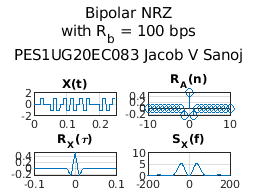

clc
close all;
clear;
% For the RZ schemes, ON-time = Tb/2
Type = 'Bipolar NRZ';
Rb = 100; % bit rate
Tr = 0.001; % Time resolution to plot the signals
Tb = 1/Rb; % Bit duration
Ttotal = 1000; % signal length = 1000 sec.
NcorrX = 100; % length of R_x(tau) = 201 samples (-0.1 sec to +0.1 sec)
NcorrA = 10; % length of R_A(n) = 21 samples (-10 to +10) 
Nfft = 512; % to compute the power spectrum
t=[0:Tr:Ttotal];
t=t(1:end-1);
Nsamples = length(t);
Nfactor = Tb/Tr; % No. of samples per bit duration
Nbits = Ttotal*Rb; % Total number of bits
At = double(randn(1,Nbits) > 0);
SxfAxis = [-200 200 0 60];
switch Type
case 'Unipolar NRZ'
PulseShape = ones(1,Nfactor);
SxfAxis = [-200 200 0 60];
case 'Unipolar RZ'
PulseShape = [ones(1,Nfactor/2) zeros(1,Nfactor/2)];
SxfAxis = [-250 250 0 20];
case 'Polar NRZ'
At = 2*At-1;
PulseShape = ones(1,Nfactor);
SxfAxis = [-200 200 0 20];
case 'Polar RZ'
At = 2*At-1;
PulseShape = [ones(1,Nfactor/2) zeros(1,Nfactor/2)];
SxfAxis = [-250 250 0 10];
case 'Bipolar NRZ'
Aindex = find(At);
Aindex = downsample(Aindex,2,1);% every alternate index is choosen
At(Aindex) = -1;
PulseShape = ones(1,Nfactor);
SxfAxis = [-200 200 0 10];
otherwise
At = 2*At-1;
PulseShape = [ones(1,Nfactor/2) -ones(1,Nfactor/2)];
SxfAxis = [-250 250 0 10];
end
Xt = kron(At,PulseShape); % Generating X(t) from A(t)
% Plotting X(t)
subplot(221)
plot(t(1:250),Xt(1:250))
grid on
axis([0 0.25 -2 2]);

sgtitle([Type, " with R_b = 100 bps ", "PES1UG20EC083 Jacob V Sanoj"])
title('X(t)')
% Plotting R_A(n)
rAt = xcorr(At,NcorrA)./Nbits;
subplot(222)
stem([-NcorrA:NcorrA],rAt);
grid on;
title('R_A(n)')
% Plotting R_x(tau)
rxt = xcorr(Xt,NcorrX)./Nsamples;
subplot(223)
plot([-NcorrX*Tr:Tr:NcorrX*Tr],rxt);
grid on;
title('R_X(\tau)')
% Plotting S_x(f)
f = ((-Nfft/2):(Nfft/2)-1)/(Nfft*Tr); % Set the frequency scale, to display the FFT output in terms of analog frequency (in Hz)
Sxf = abs(fftshift(fft(rxt,Nfft)));
subplot(224)
plot(f,Sxf)
grid on
axis(SxfAxis)
title('S_X(f)')